# Workspace & Robot Plotting - Example (made-up dimensions)

clc; clear; close all;

## Data

L = [2 1.1 3 1 1.5];
% l1a = L(1); l1b = L(2); l1c = L(3); l2 = L(4); l3 = L(5);

angle = pi/6;
limits = [-pi/6 pi/3 0 3 -0.5*pi 0.5*pi];

## Old Version

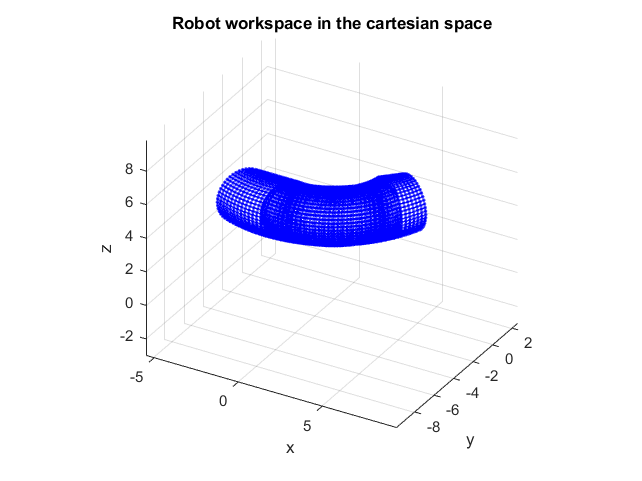

figure
plot_workspace_OLD(L,angle,limits,gcf)

## Current Version

### Workspace

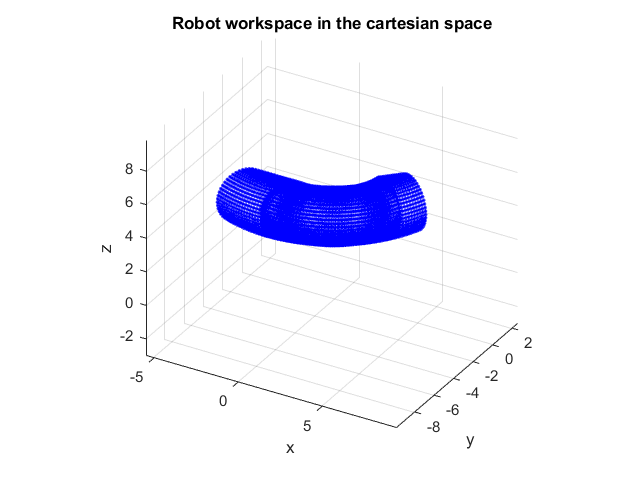

nPoints = [70 15 25];

figure
plot_workspace(L,angle,limits,gcf,nPoints)

### Manipulator

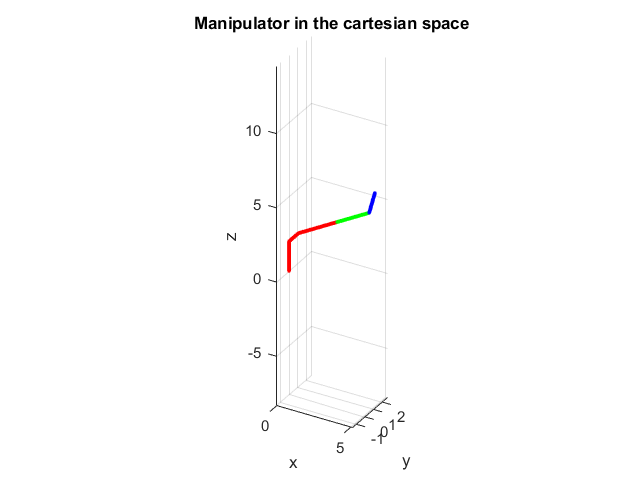

Q = {0.5*pi; 1.5; 0.25*pi};

figure
plot_robot(Q,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Manipulator in the cartesian space')

## Robot and WS according to UNI EN ISO 9787

### Projection on YZ Plane

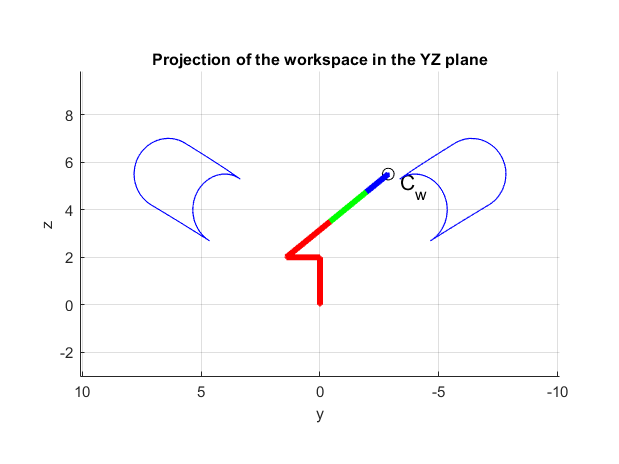

% Workspace
nPoints = [500 100 200];

figure
workspace_YZ_projection(L,angle,limits,gcf,nPoints)

% Robot with all its axes in their median position (Cw: center of the working space)
Qcw = [median(limits(1:2)); median(limits(3:4)); median(limits(5:6))];
Qcw = num2cell(Qcw);
plot_robot_bold(Qcw,L,angle,gcf)

% Plot Cw
[Scw,~] = dir_kin(Qcw,L,angle);
hold on
plot3(Scw{1},Scw{2},Scw{3},'ok','MarkerSize',8)
offset = -0.5;
text(Scw{1}+offset,Scw{2}+offset,Scw{3}+offset,'C_w','Color','black','FontSize',14);

### Projection on XY Plane

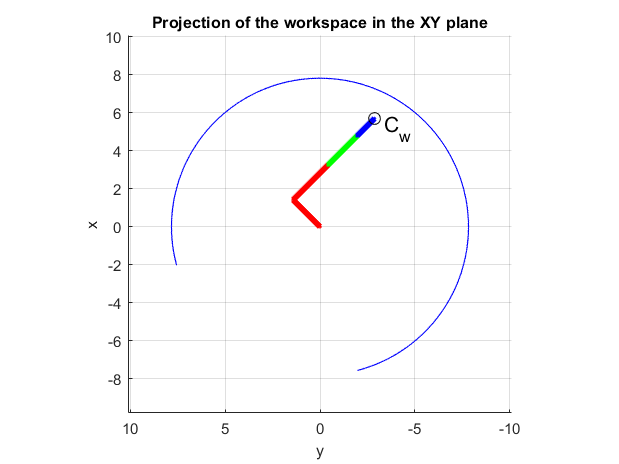

% Workspace
nPoints = [1000 100 200];

figure
workspace_XY_projection(L,angle,limits,gcf,nPoints)

% Robot with all its axes in their median position (Cw: center of the working space)
Qcw = [median(limits(1:2)); median(limits(3:4)); median(limits(5:6))];
Qcw = num2cell(Qcw);
plot_robot_bold(Qcw,L,angle,gcf)

% Plot Cw
[Scw,~] = dir_kin(Qcw,L,angle);
hold on
plot3(Scw{1},Scw{2},Scw{3},'ok','MarkerSize',8)
offset = -0.5;
text(Scw{1}+offset,Scw{2}+offset,Scw{3}+offset,'C_w','Color','black','FontSize',14);

## Check Inverse Kinematics

Q = {0.5*pi; 1.5; -0.15*pi};
[S,~] = dir_kin(Q,L,angle);

sol = 1;
Q_inv_kin = inv_kin(S,L,angle,sol);

Q0 = {0.4*pi; 1.2; 0.15*pi};
Q_inv_kin_numerical = inv_kin_numerical(S,L,angle,Q0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


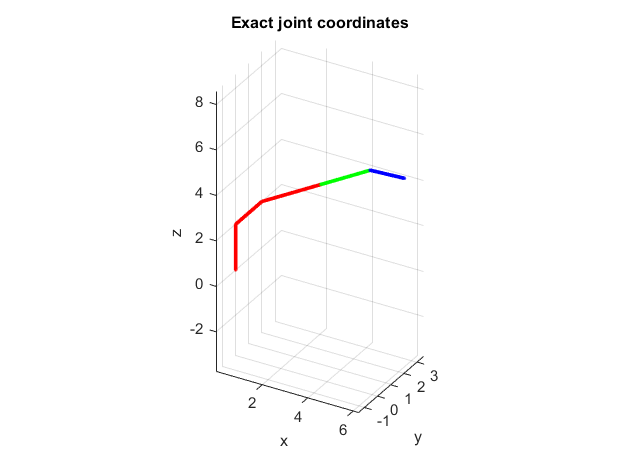

figure
plot_robot(Q,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Exact joint coordinates')

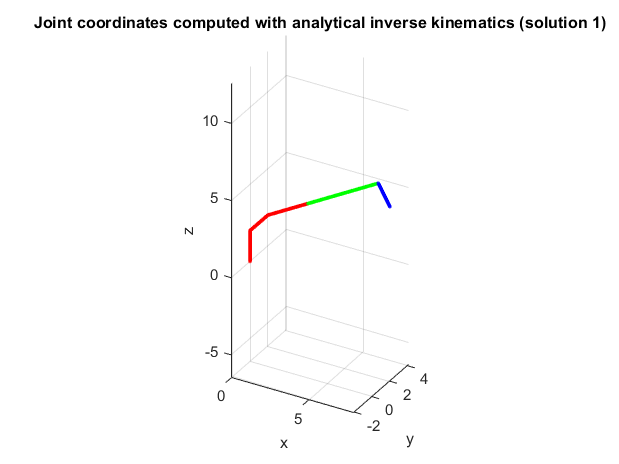

figure
plot_robot(Q_inv_kin,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Joint coordinates computed with analytical inverse kinematics (solution 1)')

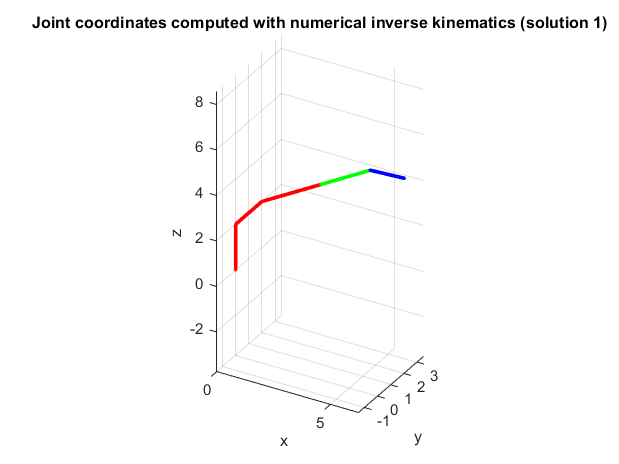

figure
plot_robot(Q_inv_kin_numerical,L,angle,gcf)
grid on
axis equal
view(30,30)
xlabel('x'); ylabel('y'); zlabel('z')
title('Joint coordinates computed with numerical inverse kinematics (solution 1)')